addpath 'Exp Data'
clc
clear all;

# Term Project Report

## Modelling

This section will deal with modelling the pendulum servo system under consideration. First, the model is presented...

### Determination of System Parameters from Experimental Data

First, the experimental data is imported and the values of system constants $K_m, ~K_t, ~K_p, $ and $K_a$ are determined using various techniques.  The data is found in the "SS_speeds_voltages_data.xlsx" excel spreadsheet located in the "Exp Data" repository sub-folder. The parameters are defined as follows:


$$\begin{array}{rl}


K_m

&= ~\frac{ \omega_{ss}}{v_m} \\

K_t

&= -~\frac{v_t}{ \omega}\\

K_p

&= ~\frac{v_p}{ \theta_o}\\

K_a

& = ~\frac{v_m}{v_o}



\end{array}$$


$K_m$ is the motor speed constant (which is related to additional motor parameters below),  the tachometer constant is $K_t$, the potentiometer constant is$K_p$, and the inverting power amplifier constant is $K_a$. The variable $\omega_{ss}$ is the motor's steady state angular velocity reached when a step input voltage of $v_m$ is applied. The voltage $v_t$ is an output of the tachometer for any given, instantanous motor angular velocity $\omega$. For the position constant, the voltage $v_p$ represents the potentiometer voltage reading given gear reduced ouput angle $\theta_o$. This output angle is related to the motor shaft angle through gear ratio $N$ (given): 

$\theta_o = \frac{\theta_m}{N}$.

In addition to these parameters, the motor/gearbox's open loop time constant $\tau_m$ must be determined from step response data provided. This, along with $K_m$ (also determined experimentally) will provide for almost all of the relationships that will be needed to model the motor within the system. Their equations are:


$$\tau_m = \frac{J_m}{K_{fm} + \frac{K_c}{R_a}K_b}$$


and 


$$K_m = \frac{ \frac{K_c}{R_a}}{K_{fm} + \frac{K_c}{R_a}K_b}$$


Where $K_{fm}$ is the motor's viscous damping coefficient, $R_a$ is its armature resistance, $K_c$ is its torque/current constant, $K_b$ is its back emf constant, and $J_m$ is the combined mass moment of inertia of the motor armature and the gearbox. 

One more experimental measurement is required - the ratio $ \frac{K_c}{R_a}$ can be determined from the static torque required to move the pendulum from equilibrium when it is at -90 degrees (horizontal). This static torque-voltage constant is found from: 


$$ \frac{K_c}{R_a} = \frac{MgL}{v_{m,0}}$$


where $M$is the mass of the pendulum bob, $g$ is the gravitational constant, and $L$ is the moment arm from the pendulum's point of rotation to the pendulum bob. 

%%Set up the Import Options and Import the Steady State Speed vs. Voltage Data

%This portion of code was generated automatically in MATLAB using the "Import Data" tool ]
%and its "Generate Live Script" functionality. The file path for the readtable function call 
% has been modified to work with the file system scheme used in this report. Additionally, 
% the data originally output as an array is transfered into the struct "SS_w_v_dat". 
opts = spreadsheetImportOptions("NumVariables", 4);

% Specify sheet and range
opts.Sheet = "Sheet1";
opts.DataRange = "A3:D13";

% Specify column names and types
opts.VariableNames = ["MotorSpeed", "Vo", "Vm", "VT"];
opts.VariableTypes = ["double", "double", "double", "double"];

% Import the data
SSspeedsvoltagesdata = readtable("F:\Sourcetree Repos\Matlab Personal\EE 514\Term Project\Exp Data\SS_speeds_voltages_data.xlsx", opts, "UseExcel", false);

SSspeedsvoltagesdata = 11×4 table
    MotorSpeed      Vo        Vm       VT  
    __________    ______    ______    _____

          0            0    -0.025        0
        650       -0.873      4.25     -9.8
        900       -1.061      5.36    -13.5
       1450       -1.463       7.6    -21.4
       1800       -1.762      9.26    -27.1
       2200        -2.04     10.86      -33
          0        0.223     0.774        0
        245       -0.463      2.06     -3.6
        140       -0.368      1.56    -1.65
          0       -0.271      1.07        0
         60        -0.32       1.3    -1.01


%%Convert to output type to an array and then fill a struct with the data 
SSspeedsvoltagesdata = table2array(SSspeedsvoltagesdata);
SS_w_v_dat.MotorSpeed = SSspeedsvoltagesdata(:,1);
SS_w_v_dat.Vm = SSspeedsvoltagesdata(:,3);
SS_w_v_dat.Vt = SSspeedsvoltagesdata(:,4);

%%Clear temporary variables
clear opts SSspeedsvoltagesdata

%%Sort the Data By Increasing Values of Motor Speed
[MotorSpeed, I] = sort(SS_w_v_dat.MotorSpeed);
SS_w_v_dat.MotorSpeed = MotorSpeed;
SS_w_v_dat.Vm = SS_w_v_dat.Vm(I);
SS_w_v_dat.Vt = SS_w_v_dat.Vt(I);
clear MotorSpeed

%%Set up the Import Options and Import the Position Sensor Data

#### Determine the Motor Speed Constant and the Deadzone Voltage

DZ_index = SS_w_v_dat.MotorSpeed == 0;

$K_m $ is determined from the slope of a linear curve fit to the non-deadzone data points.

Km_fit = polyfit(SS_w_v_dat.Vm(~DZ_index),SS_w_v_dat.MotorSpeed(~DZ_index),1);
fprintf(['Km is determined to be ' num2str(round(Km_fit(1),1)) ' [RPM/V]'])

Km is determined to be 220.9 [RPM/V]

Deadzone voltage, $v_{DZ}$, is determined by finding x intercept of the linear curve fit to all non-zero voltage data points.

DZ_voltage = -Km_fit(2)/Km_fit(1);
fprintf(['Deadzone voltage is determined to be ' num2str(DZ_voltage) ' [V]'])

Deadzone voltage is determined to be 1.0684 [V]

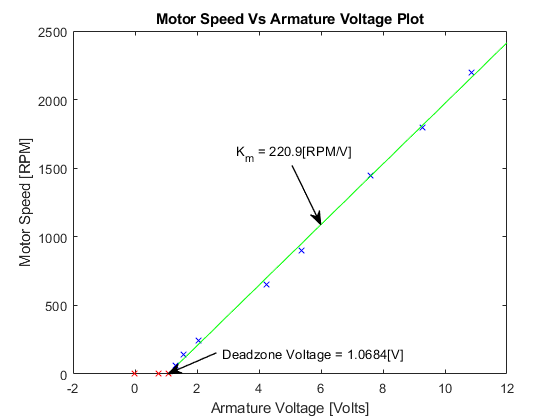


plot(SS_w_v_dat.Vm(DZ_index),SS_w_v_dat.MotorSpeed(DZ_index), 'r x',SS_w_v_dat.Vm(~DZ_index),SS_w_v_dat.MotorSpeed(~DZ_index), 'b x', [DZ_voltage 12],[0 Km_fit(1)*12 + Km_fit(2)],'g')
xlabel('Armature Voltage [Volts]')
ylabel('Motor Speed [RPM]')
title('Motor Speed Vs Armature Voltage Plot')

%Deadzone Location Annotation
ax = gca;
LArr = .1; %Length of Arrow
PhiArr = deg2rad(30);
%Arrow Head
[xh, yh] = ds2nfu(ax,SS_w_v_dat.Vm(length(SS_w_v_dat.Vm(DZ_index))), 0);
%Arrow Tail
xt = xh + LArr*cos(PhiArr);
yt = yh + LArr*sin(PhiArr);
annotation('textarrow',[xt xh],[yt yh],'String',['Deadzone Voltage = ' num2str(round(DZ_voltage,4)) '[V]'],'FontSize',10,'Linewidth',1)

%Slope Annotation
ax = gca;
LArr = .15; %Length of Arrow
PhiArr = deg2rad(110);
%Arrow Head
[xh, yh] = ds2nfu(ax,6, Km_fit(1)*6 + Km_fit(2));
%Arrow Tail
xt = xh + LArr*cos(PhiArr);
yt = yh + LArr*sin(PhiArr);
annotation('textarrow',[xt xh],[yt yh],'String',['K_m = ' num2str(round(Km_fit(1),1)) '[RPM/V]'],'FontSize',10,'Linewidth',1)

#### Determine the Tachometer Constant

A linear curve fit is used to approximate the tachometer measurement constant $K_t = -\frac{v_t}{\omega}$  from experimental data. 

Kt_fit = polyfit(SS_w_v_dat.MotorSpeed,SS_w_v_dat.Vt,1);
fprintf(['Kt is determined to be ' num2str(round(-Kt_fit(1),3)) ' [V/RPM]'])

Kt is determined to be 0.015 [V/RPM]

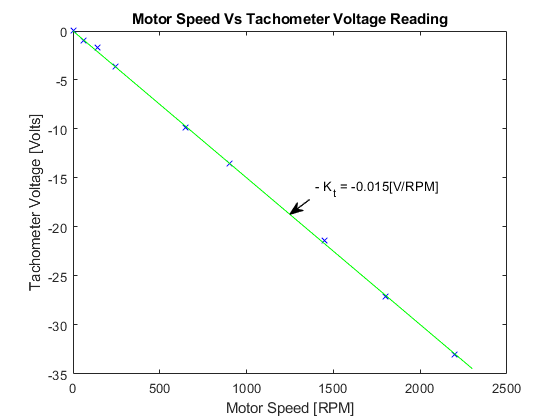


plot(SS_w_v_dat.MotorSpeed,SS_w_v_dat.Vt, 'b x',[0 2300],[0 Kt_fit(1)*2300 + Kt_fit(2)],'g' )
xlabel('Motor Speed [RPM]')
ylabel('Tachometer Voltage [Volts]')
title('Motor Speed Vs Tachometer Voltage Reading')

%Slope Annotation
ax = gca;
LArr = .05; %Length of Arrow
PhiArr = deg2rad(45);
%Arrow Head
[xh, yh] = ds2nfu(ax,1250, Kt_fit(1)*1250 + Kt_fit(2));
%Arrow Tail
xt = xh + LArr*cos(PhiArr);
yt = yh + LArr*sin(PhiArr);
annotation('textarrow',[xt xh],[yt yh],'String',['- K_t = ' num2str(round(Kt_fit(1),3)) '[V/RPM]'],'FontSize',10,'Linewidth',1)

### Relating Found System Parameters to the Nonlinear Motorized Pendulum Model